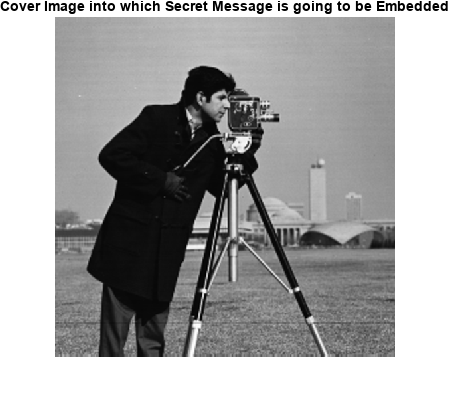

clear all;
clc;

% Cover Image into which Secret Message is Embedded
input = imread('cameraman.tif');
input=imresize(input, [512 512]);
imshow(input)
title("Cover Image into which Secret Message is going to be Embedded")


% Secret Message to be embedded
message='This is Group C3 Project and we are doing Encrypted communication using Images. This is LSB steganograpghy where the secret message is embedded into the LSB of a pixel Intensity of an Image , followed by end to end communication that includes BPSK modulation and Repetition 3 encoding and Hard Decision Decoding and the Transmitter passes signal through AWGN channel';

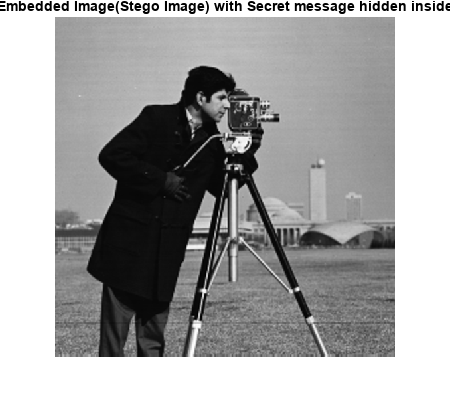

% LSB IMAGE STEGANOGRAPHY WHERE THE IMAGE PIXELS 
% LEAST SIGNITFIACT BIT OF 8 BITS USED TO REPRESENT 
% PIXELS INTENSITY

% Length of the message where each character is 8 bits
len = length(message) * 8 ;

% Convert to ASCII values 
ascii_value = uint8(message);
 
% Convert the decimal values to binary
bin_message = transpose(dec2bin(ascii_value, 8));
 
% Get all the binary digits in separate row
bin_message = bin_message(:);
 
% Length of the binary message
N = length(bin_message);
 
% Converting the char array to numeric array
bin_num_message = str2num(bin_message);
 
% Initialize output
output = input;
 
% Get height and width for traversing through the image
height = size(input, 1);
width = size(input, 2);
 
% Counter for number of embedded bits
embed_counter = 1;
 
% Traverse through the image
for i = 1 : height
    for j = 1 : width
         
        % If more bits are remaining to embed
        if(embed_counter <= len)
             
            % Finding the Least Significant Bit of the current pixel
            LSB = mod(double(input(i, j)), 2);
             
            % Find whether the bit is same or needs to change using XOR
            % operation
            temp = double(xor(LSB, bin_num_message(embed_counter)));
             
            % Updating the output to input + temp
            output(i, j) = input(i, j) + temp ;
             
            % Increment the embed counter
            embed_counter = embed_counter + 1;
        end
         
    end
end

imshow(output)
title("Embedded Image(Stego Image) with Secret message hidden inside")

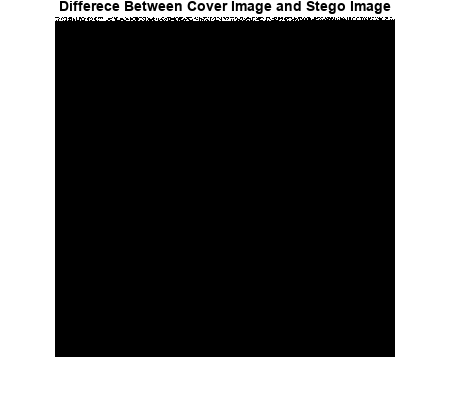

imshow((output-input)*10000) 
title("Differece Between Cover Image and Stego Image")

% Convert Image into Bitsream for Communication
s = size(output);
B = dec2bin(output(:), 8)';
C = B(:)' - '0';

% Apply BPSK modulation, repetition encoding, and hard decision decoding
Eb_Nodb = 1;
Eb_No = 10 .^ (Eb_Nodb/10);
n = 3;
k = 1;
R = k/n;
sigma_coded = sqrt(1/(2*Eb_No));
% Initialize the Transmitter's Output
comm_out = zeros(1, n);

disp(length(C))

     2097152



% Transmitter and Receiver
for j = 1:length(C)
    % Take a single value of bitstream
    msg = C(j);
% TRANSMITTER
    % Repetition 3 encoding
    msg_encoded = [msg msg msg];
    % BPSK modulation
    mod_out = -1 + 2 * msg_encoded;
% CHANNEL
    % Add Gussian noise
    channel_out = mod_out + sigma_coded * randn(1, n);
% RECEIVER    
    % demodulating
    demod_out = channel_out > 0;
    % Hard decision decoding and output of end to end communication
    comm_out(j) = sum(demod_out) >= 2;
end

% Convert  Bitsream into Image for Decryption
bitstream = num2str(comm_out); bitstream = bitstream(bitstream ~= ' ');
disp(size(bitstream));

           1     2097152



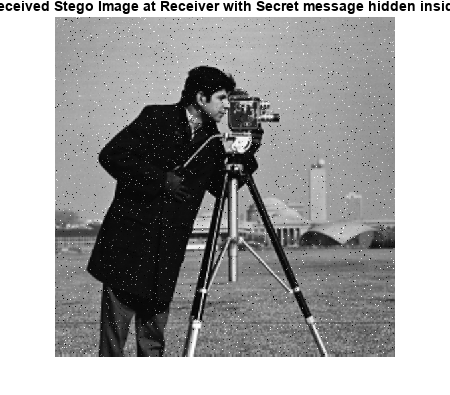

X = uint8(bin2dec(reshape(num2str(bitstream), 8, [])'));
I = reshape(X, s);
imshow(I);
title("Received Stego Image at Receiver with Secret message hidden inside")

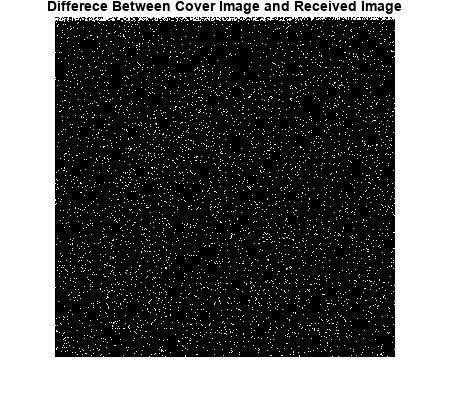

imshow((I-input)*10000) 
title("Differece Between Cover Image and Received Image")

% Initialize a variable to store the extracted binary message
extracted_bin_message = '';

% Initialize a counter to keep track of the number of extracted bits
extract_counter = 1;

% Traverse through the image
for i = 1 : height
    for j = 1 : width
        % If more bits can be extracted
        if (extract_counter <= len)

            % Extract the LSB of the current pixel
            LSB = mod(double(I(i, j)), 2);
            
            % Append the extracted bit to the binary message
            extracted_bin_message = [extracted_bin_message, num2str(LSB)];
            
            % Increment the extract counter
            extract_counter = extract_counter + 1;
            
        else
            break;  % All bits have been extracted, exit the loop
        end
    end
    if (extract_counter > len)
        break;  % All bits have been extracted, exit the loop
    end
end

% Convert the binary secret message back to text
extracted_ascii_values = reshape(extracted_bin_message, 8, []).';
extracted_decimal_values = bin2dec(extracted_ascii_values);

% Concatenate the extracted decimal values into a single string
extracted_message = char(extracted_decimal_values)';

% Display the extracted message
disp(extracted_message);

This as Group C30Project and we are doing Encrypted communicition Using Imaees> This is LSB stegaîogr!pghy where the 3ecret messagm`is embeddmd into the LSB of a pixel Intensity oF an Image , fïllowed by eld to end commun{cation that includes BPSK moduìa4ion and Ruð%tition 3 enCoding and Hard Desision Decoding anf the Transmitter pqsses signal througH AWGN chánndl



% Specify the file name to save the extracted message
filename = 'extracted_message.txt';

% Write the extracted message to the file
dlmwrite(filename, extracted_message, '');

disp(['Extracted message saved to file: ', filename]);

Extracted message saved to file: extracted_message.txt
